figure
plot(NY.X,NY.Y)
hold on

X = linspace(NY.BoundingBox(1,1),NY.BoundingBox(2,1),100);
Y = linspace(NY.BoundingBox(1,2),NY.BoundingBox(2,2),100);
population = zeros(100,100);
[x,y]=meshgrid(X,Y);

for i=1:62
plot(NYS(1).X,NYS(1).Y)
temp1 = NYS(i).X;
temp2 = NYS(i).Y;
a(i) = sum(temp1(:,1:(length(NYS(i).X')-1)))/(length(NYS(i).X')-1);
b(i) = sum(temp2(:,1:(length(NYS(i).Y')-1)))/(length(NYS(i).Y')-1);
in = inpolygon(x,y,NYS(i).X,NYS(i).Y);
inPop =  NYS(i).POP2010* in;
population = population + inPop;
temp1=0;
temp2=0;
in = 0;
end

population

population =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0

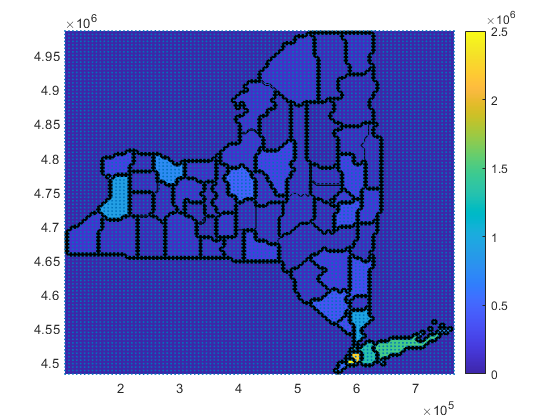


contourf(X,Y,population,v)
%scatter(a,b)
colorbar

[x,y]=meshgrid(X,Y);
scatter(x(:),y(:),1)